## Problem 2

**(45 points)** The file `noisy_signal.txt` contains pairs of points $(t_k,f(t_k))$ which represents $1000$ equally spaced samples of the function $f$ on the time interval $[0, 2\pi)$. 				

**(a)** Make a plot of the data, $f$ vs. $t$. In Matlab, you can read in the data using the command `load` or `dlmread` and in Python use the `loadtxt` command in the `numpy` library.

figure(1)
signal = readmatrix("noisy_signal.txt");
signal

signal =          0   -0.3211
    0.0063   -0.2794
    0.0126   -0.3377
    0.0188   -0.4075
    0.0251   -0.0097
    0.0314   -0.5546
    0.0377   -0.2125
    0.0440   -0.4055
    0.0503   -0.5176
    0.0565   -0.4390


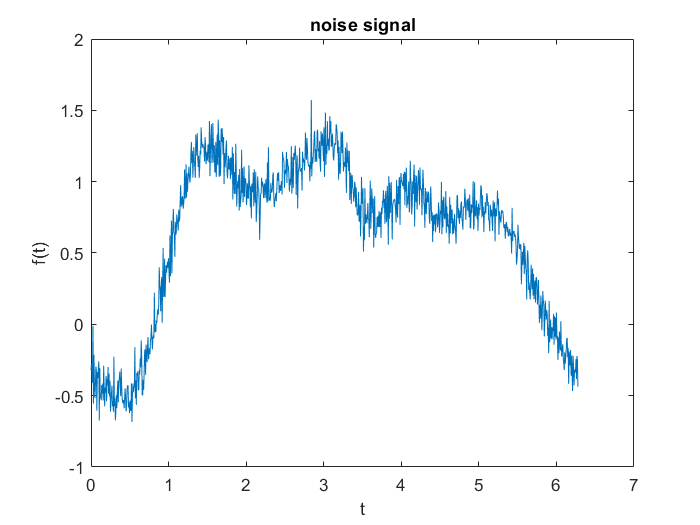

t_signal = signal(:,1);
f_signal = signal(:,end);
plot(t_signal,f_signal)
title("noise signal")
xlabel("t"); ylabel("f(t)");

**(b)** Use the `fft` command to compute the discrete Fourier transform of the data. Let $c_k$ be the complex-valued Fourier coefficients. Make a plot of $|c_k|$ vs. $k$ for $k = 0, \dots , 500$. Use log scales for both axes. In both Matlab and Python, you can evaluate the modulus of a complex number using the `abs` function. What can you conclude from this plot? 

There are $1000$ data points, and the `fft` will return $1000$ complex valued Fourier coefficients. The discrete Fourier coefficients from the `fft` algorithm (both Matlab and Python) are ordered as


$$(c_0,c_1,\dots,c_{500},c_{-499},c_{-498},\dots,c_{-2},c_{-1}).$$
		

dft = fft(f_signal)

dft = 	1.0e+02 *

   6.3662 + 0.0000i
  -3.0396 - 0.1169i
  -1.5996 + 0.8616i
  -0.8774 + 0.6906i
   0.3676 + 0.5392i
   0.1397 - 0.4096i
   0.2431 - 0.0271i
  -0.1722 + 0.0190i
   0.0989 - 0.0697i
  -0.0377 + 0.0324i


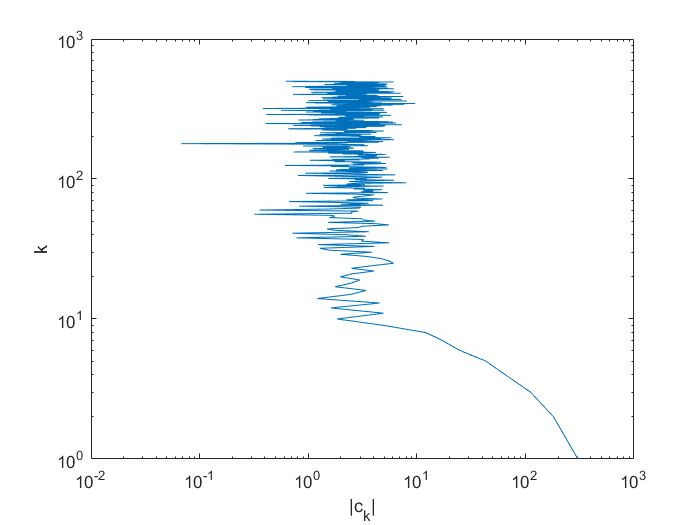

k = [0:499];

figure(2)
loglog(abs(dft(1:500)),k)
xlabel("|c_k|");ylabel("k");


% to see the difference
% figure(3)
% loglog(abs(dft(1:500)),k)
% xlabel("|c_k|");ylabel("k");

**(c)** Let $f_s$ represent a smoothed version of the $f$ with the high frequency components removed. To smooth the data, filter out the high frequency components by setting the discrete Fourier coefficients, $c_k$, to zero for $|k| > 10$. To generate the time samples of $f_s$, use the `ifft` command. Plot $f_s$ vs. $t$. 

dft(10:end) = 0;
fs_signal = ifft(dft)

fs_signal =    0.1527 + 0.1487i
   0.1507 + 0.1451i
   0.1487 + 0.1416i
   0.1467 + 0.1380i
   0.1447 + 0.1344i
   0.1427 + 0.1307i
   0.1407 + 0.1271i
   0.1387 + 0.1234i
   0.1367 + 0.1197i
   0.1347 + 0.1160i



figure(4)
plot(t_signal,fs_signal)

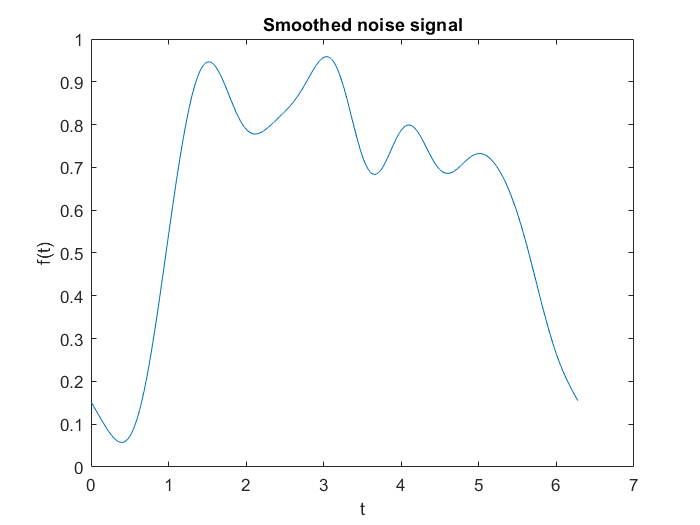

title("Smoothed noise signal")
xlabel("t"); ylabel("f(t)");